## Análisis cinemático

clear
clc


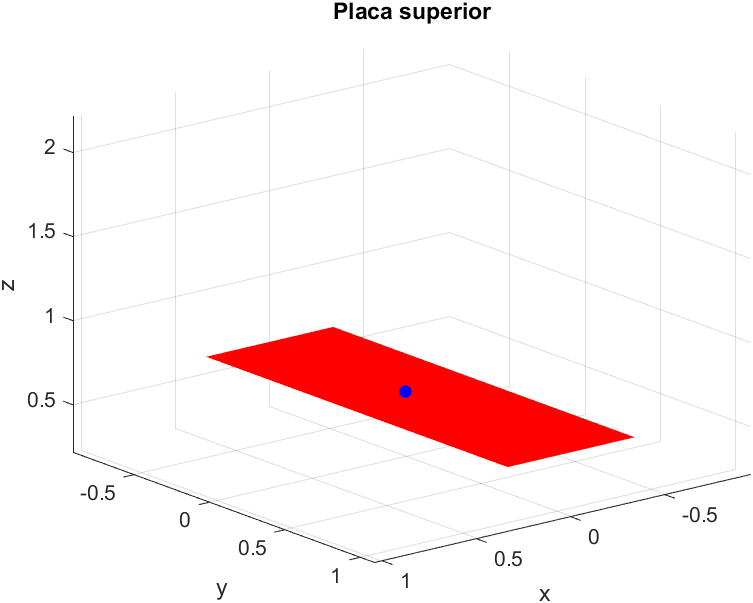

b=2.3;
h=0.675;

syms beta(t) theta(t) x y z Xa(t) Za(t)
Pi=[x y z];



### Ecuaciones generales


Wbeta(t)=[beta(t) 0 0];
Wtheta(t)=[0 theta(t) 0];
Wtotal(t)=diff(Wbeta(t)+Wtheta(t));

VelocidadPO(t)=cross(Wtotal(t),Pi);
aceleracionAngular(t)=diff(Wtotal(t));

AceleracionPO(t)=cross(aceleracionAngular(t),Pi)+cross(Wtotal(t),VelocidadPO(t));


Velocidad=formula(VelocidadPO(t)+diff([Xa(t) 0 Za(t)]));
Vx=Velocidad(1)

$$Vx = z\,\frac{\partial }{\partial t}\theta \left(t\right)+\frac{\partial }{\partial t}\mathrm{Xa}\left(t\right)$$

Vy=Velocidad(2)

$$Vy = -z\,\frac{\partial }{\partial t}\beta \left(t\right)$$

Vz=Velocidad(3)

$$Vz = y\,\frac{\partial }{\partial t}\beta \left(t\right)-x\,\frac{\partial }{\partial t}\theta \left(t\right)+\frac{\partial }{\partial t}\mathrm{Za}\left(t\right)$$


Aceleracion=formula(AceleracionPO(t)+diff(diff([Xa(t) 0 Za(t)])));
Ax=Aceleracion(1)

$$Ax = z\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+\left(y\,\frac{\partial }{\partial t}\beta \left(t\right)-x\,\frac{\partial }{\partial t}\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+\frac{\partial^{2}}{\partial t^{2}}\mathrm{Xa}\left(t\right)$$

Ay=Aceleracion(2)

$$Ay = -\left(y\,\frac{\partial }{\partial t}\beta \left(t\right)-x\,\frac{\partial }{\partial t}\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)-z\,\frac{\partial^{2}}{\partial t^{2}}\beta \left(t\right)$$

Az=Aceleracion(3)

$$Az = y\,\frac{\partial^{2}}{\partial t^{2}}\beta \left(t\right)-z\,{\left(\frac{\partial }{\partial t}\beta \left(t\right)\right)}^{2}-z\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-x\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+\frac{\partial^{2}}{\partial t^{2}}\mathrm{Za}\left(t\right)$$